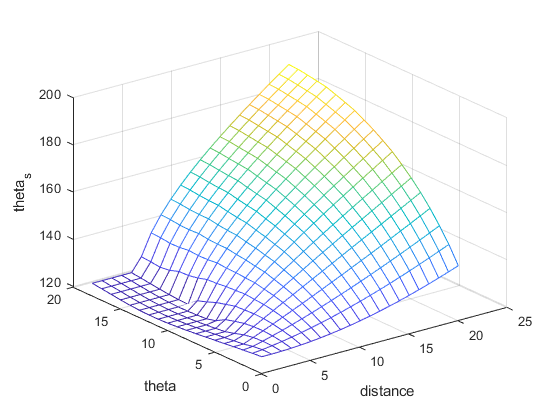

h_1=92.5;
h_2=74;
l_1=140;
l_2=150;
h_r=97.5;
h_s=22.3;
w_s=204.3;
l_s=72;
l_r=160;
d_w=31;             %% original value -> d_w = 45
r=248;
pi=3.141592;

%%initial angle = 47.0459(in straight pipe)

for theta = 0:90
    %i= r*tan(11.25*pi/180)*(sin(theta*pi/180)+1)-r*tan(11.25*pi/180);
    %st=abs((1+sin(theta))*r*tan(11.25*pi/180));
    j= 253-50  ; %253
    for s = 0:j
        
       % stt=(j-1+49-st)/90;
        
        %%alpha=0
%           equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2 ...  
%           )*cos(theta*pi/180))^2/r^2 + ...
%           ((tan(11.25*pi/180)+tan(67.5*pi/180))*(l_s*cos(x)+d_w/2* ...
%           sin(((67.5)*sin(theta*pi/180))*pi/180) ...
%           *sin(theta*pi/180)+r+h_s-h_r)* ...
%           sin(theta*pi/180)+s)^2/(r/sin(22.5*pi/180))^2-1;

%%modified by adding some equation about l_s
%           equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2 ...  
%           )*cos(theta*pi/180))^2/r^2 + ...
%           ((tan(11.25*pi/180)+tan(67.5*pi/180))*(l_s*cos(x)+d_w/2* ...
%           cos(((22.5)*sin(theta*pi/180))*pi/180) ...
%           *sin(theta*pi/180)+r+h_s-h_r)* ...
%           sin(theta*pi/180)+d_w/2*(sin(22.5*pi/180)-cos(22.5*pi/180)*tan(11.25*pi/180))...
%           *sin(theta*pi/180)+s+l_s*(sin(x)-sin(42.9504*pi/180)))^2/(r/sin(22.5*pi/180))^2-1;
      
%%================WORKED!!!!!!!!!!!!!!!!!!!!=======================
%           equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2 ...  
%           )*cos(theta*pi/180))^2/r^2 + ...
%           (tan(67.5*pi/180)*(l_s*cos(x)+d_w/2*cos(22.5*pi/180)*sin(theta*pi/180)+r+h_s-h_r)* ...
%           sin(theta*pi/180) ...
%           -(253-49*theta/90)+s+w_s+l_s*sin(x)+d_w/2*sin(22.5*pi/180)*sin(theta*pi/180)...
%           -d_w/2*sin(22.5*pi/180)*(1-cos(22.5*pi/180)*tan(22.5*pi/180)))^2/(r/sin(22.5*pi/180))^2-1;

%             equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2 ...  
%           )*cos(theta*pi/180))^2/r^2 + ...
%           (tan(67.5*pi/180)*(l_s*cos(x)+d_w/2*cos(22.5*pi/180)*theta/90+r+h_s-h_r)* ...
%           theta/90 ...
%           -(253-49*theta/90)+s+w_s+l_s*sin(x)+d_w/2*sin(22.5*pi/180)*theta/90 ...
%           -d_w/2*sin(22.5*pi/180)*(1-cos(22.5*pi/180)*tan(22.5*pi/180)))^2/(r/sin(22.5*pi/180))^2-1;

      
        %%alpha=10
%           equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2*cos(s/j*10*pi/180) ...  
%           )*cos(theta*pi/180))^2/r^2 + ...
%           (tan(67.5*pi/180)*(l_s*cos(x)+d_w/2* ...
%           cos(((90-80*s/j-(67.5-80*s/j))*sin(theta*pi/180))*pi/180) ...
%           *sin(theta*pi/180)+r+h_s-h_r)* ...
%           sin(theta*pi/180)-(253-49*theta/90)+s...
%           +w_s+l_s*sin(x)+d_w/2*sin(22.5*pi/180)*sin(theta*pi/180)...
%           -d_w/2*sin(((90-80*s/j-(67.5-80*s/j))*sin(theta*pi/180))*pi/180)*(1-cos(22.5*pi/180)*tan(22.5*pi/180)))^2/(r/sin(22.5*pi/180))^2-1;
            equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2*cos((10*s/j+(22.5-10*s/j)*theta/90)*pi/180) ...  
          )*cos(theta*pi/180))^2/r^2 + ...
          (tan(67.5*pi/180)*(l_s*cos(x)+d_w/2*cos((10*s/j+(10-10*s/j)*theta/90)*pi/180)...
          +r+h_s-h_r)*cos((90-theta)*pi/180) ...
          -(253-49*sin(theta*pi/180))+s+w_s+l_s*sin(x)+d_w/2*sin((10*s/j+(22.5-10*s/j)*theta/90)*pi/180)...
          +d_w/2*sin(((10*s/j-(22.5*s/j-10))*sin(theta*pi/180))*pi/180)*...
          (1-cos(((10*s/j-(22.5*s/j-10))*theta/90)*pi/180)...
          *tan(((10*s/j-(22.5*s/j-10))*theta/90)*pi/180))*sin(theta*pi/180))^2/(r/sin(22.5*pi/180))^2-1;



        %%alpha=22.5(worked)
%            equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2*cos((22.5*s/j+(22.5-22.5*s/j)*theta/90)*pi/180) ...  
%           )*cos(theta*pi/180))^2/r^2 + ...
%           (tan(67.5*pi/180)*(l_s*cos(x)+d_w/2*cos((22.5*s/j+(22.5-22.5*s/j)*theta/90)*pi/180)...
%           +r+h_s-h_r)*cos((90-theta)*pi/180) ...
%           -(253-49*sin(theta*pi/180))+s+w_s+l_s*sin(x)+d_w/2*sin((22.5*s/j+(22.5-22.5*s/j)*theta/90)*pi/180)...
%           +d_w/2*sin(((22.5*s/j-(22.5*s/j-22.5))*sin(theta*pi/180))*pi/180)*...
%           (1-cos(((22.5*s/j-(22.5*s/j-22.5))*theta/90)*pi/180)...
%           *tan(((22.5*s/j-(22.5*s/j-22.5))*theta/90)*pi/180))*sin(theta*pi/180))^2/(r/sin(22.5*pi/180))^2-1;
      

          b(theta+1,s+1)=fzero(equation,1)*180/pi+90;
%         end
    end
end

for theta=0:90
    for s=0:j
          deltad(theta+1,s+1)=(l_s*cos((b(theta+1,s+1)-90)*pi/180)+d_w/2* ...
          sin((90-10*s/j-(22.5-10*s/j)*sin(theta*pi/180))*pi/180) ...
          *sin(theta*pi/180)+r+h_s-h_r)* ...
          sin(theta*pi/180);
    end
end


%%% s=0, the start point values

for i=0:90
    distance(i+1)=248*sin(i*pi/180);
    y_distance(i+1)=distance(i+1)*tan(11.25*pi/180);
    fix_value(i+1)=round(y_distance(i+1));
end

for i=0:90
    if fix_value(i+1) ~= 0
            for k1=0:203-fix_value(i+1)
                b(i+1,204-k1)=b(i+1,204-k1-fix_value(i+1));
            end
            for k2=1:fix_value(i+1)
                b(i+1,k2)=b(i+1,1);
            end
    end
end

for theta=0:18
    for s=0:20
          real_theta(theta+1,s+1)=b(theta*5+1,s*10+4);
    end
end

mesh(real_theta);
xlabel 'distance'
ylabel 'theta'
zlabel 'theta_s'